clear all

data = importdata("Assignment_Data_SC42145_2022.mat");
FWT=data.FWT;
eye(2)

ans =      1     0
     0     1


G1 = FWT(1:2,1:2)

G1 =
 
  A = 
                 Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (m)
   Omega (rad/s        -0.422       -0.2204             0       -0.2204             0
   z1dot (m/s)        0.02328      -0.01085         -0.04     -0.009574             0
   z1 (m)                   0             1             0             0             0
   z2dot (m/s)         0.1455      -0.05984             0       -0.1651        -10.82
   z2 (m)                   0             0             0             1             0
 
  B = 
                 Beta (deg)  tau_e (Nm)
   Omega (rad/s    -0.07988   -0.009564
   z1dot (m/s)    -0.006722           0
   z1 (m)                 0           0
   z2dot (m/s)     -0.04202           0
   z2 (m)                 0           0
 
  C = 
                 Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (m)
   Omega (rad/s             1             0             0             0             0
   z (m)                    0           

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G = G1.C*inv((s*eye(5)-G1.A))*G1.B

G =
 
  From input 1 to output...
                                                                                               
       -0.07988 s^14 - 0.09884 s^13 - 2.654 s^12 - 2.906 s^11 - 29.62 s^10 - 28.22 s^9         
                                                                                               
               - 114.1 s^8 - 91.37 s^7 - 33.67 s^6 - 11.32 s^5 - 2.878 s^4 - 0.4741 s^3        
                                                                                               
                                                          - 0.09734 s^2 - 0.006633 s - 0.001154
                                                                                               
   1:  ----------------------------------------------------------------------------------------
                                                                                               
       s^15 + 1.794 s^14 + 34 s^13 + 53.72 s^12 + 391.7 s^11 + 533.8 s^10 + 1611 s^9           
      

omega = [0, 0.6*pi];
    for i =1:length(omega)
        Gf=freqresp(G,omega(i));
        RGAw(:,:,i)=Gf.*inv(Gf).';
        RGAno(i)=sum(sum(abs(RGAw(:,:,i)-eye(2))));
        
    end
    RGA = frd(RGAw,omega)

RGA =

  From input 1 to:

    Frequency(rad/s)         output 1          output 2    
    ----------------         --------          --------    
         0.0000         -0.6554 + 0.0000i  1.6554 + 0.0000i
         1.8850         -0.0283 + 0.1398i  1.0283 - 0.1398i

  From input 2 to:

    Frequency(rad/s)        output 1           output 2    
    ----------------        --------           --------    
         0.0000         1.6554 + 0.0000i  -0.6554 + 0.0000i
         1.8850         1.0283 - 0.1398i  -0.0283 + 0.1398i
 
Continuous-time frequency response.



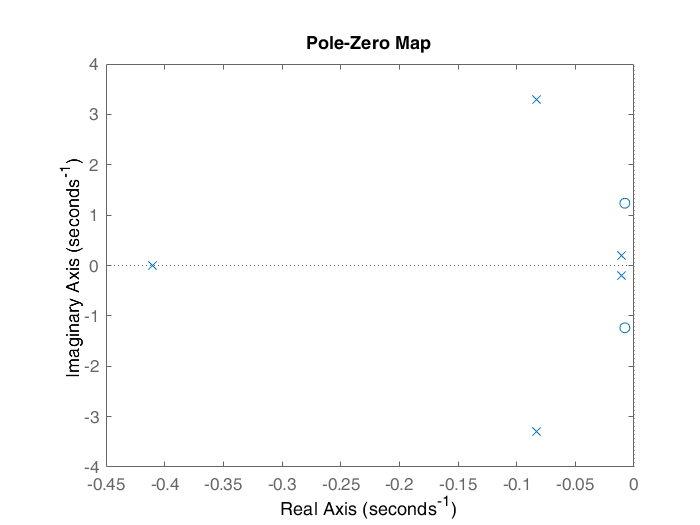

pzplot(FWT(1:2,1:2))

poles = pole(FWT(1:2,1:2))

poles =   -0.0832 + 3.2936i
  -0.0832 - 3.2936i
  -0.4104 + 0.0000i
  -0.0106 + 0.2022i
  -0.0106 - 0.2022i


zeros = zero(FWT(1:2,1:2))

zeros =   -0.0078 + 1.2358i
  -0.0078 - 1.2358i



G=tf(FWT(1:2,1:2))

G =
 
  From input "Beta (deg)" to output...
                   -0.07988 s^4 - 0.003315 s^3 - 0.8677 s^2 + 0.006493 s - 0.03458
   Omega (rad/s):  ---------------------------------------------------------------
                    s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
                  -0.04874 s^3 - 0.03481 s^2 - 0.07497 s - 0.052
   z (m):  ------------------------------------------------------------
           s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
  From input "tau_e (Nm)" to output...
                   -0.009564 s^4 - 0.001683 s^3 - 0.1039 s^2 - 0.001187 s - 0.00414
   Omega (rad/s):  ----------------------------------------------------------------
                     s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
                      -0.001614 s^2 - 2.522e-05 s - 0.002465
   z (m):  ------------------------------------------------------------
           s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827


wB1=0.3*2*pi; % desired closed-loop bandwidth
wB2=0.2; % desired closed-loop bandwidth
A=1/10000; % desired disturbance attenuation inside bandwidth
M=3 ; % desired bound on hinfnorm(S)
Wp11=tf([1/M wB1],[1 wB1*A])

Wp11 =
 
  0.3333 s + 1.885
  ----------------
   s + 0.0001885
 
Continuous-time transfer function.



Wp=[Wp11 0; 0 wB2] %

Wp =
 
  From input 1 to output...
       0.3333 s + 1.885
   1:  ----------------
        s + 0.0001885
 
   2:  0
 
  From input 2 to output...
   1:  0
 
   2:  0.2
 
Continuous-time transfer function.



%Sensitivity weight
Wu22 =(5e-3*s^2+7e-4*s+5e-5)/(s^2+14e-4*s+1e-6);
Wu=[0.01 0; 0 Wu22]; % Control weight
Wt=[] % Empty weight


Wt =

     []




P11=[Wp;zeros(2)];
P12=[Wp*-G;Wu];
P21=eye(2);
P22=-G;

P=[P11 P12; P21 P22]

P =
 
  From input 1 to output...
       0.3333 s + 1.885
   1:  ----------------
        s + 0.0001885
 
   2:  0
 
   3:  0
 
   4:  0
 
   Omega (rad/s):  1
 
   z (m):  0
 
  From input 2 to output...
   1:  0
 
   2:  0.2
 
   3:  0
 
   4:  0
 
   Omega (rad/s):  0
 
   z (m):  1
 
  From input "Beta (deg)" to output...
        0.02663 s^5 + 0.1517 s^4 + 0.2955 s^3 + 1.633 s^2 - 0.0007121 s + 0.06518
   1:  ---------------------------------------------------------------------------
       s^6 + 0.5981 s^5 + 10.98 s^4 + 4.711 s^3 + 0.543 s^2 + 0.1828 s + 3.444e-05
 
             0.009748 s^3 + 0.006961 s^2 + 0.01499 s + 0.0104
   2:  ------------------------------------------------------------
       s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
   3:  0.01
 
   4:  0
 
                   0.07988 s^4 + 0.003315 s^3 + 0.8677 s^2 - 0.006493 s + 0.03458
   Omega (rad/s):  --------------------------------------------------------------
                    s^5 + 0.5979 

%P = augw(minreal(G),Wp,Wu,Wt)
P=minreal(P)

P =
 
  From input 1 to output...
       0.3333 s + 1.885
   1:  ----------------
        s + 0.0001885
 
   2:  0
 
   3:  0
 
   4:  0
 
   Omega (rad/s):  1
 
   z (m):  0
 
  From input 2 to output...
   1:  0
 
   2:  0.2
 
   3:  0
 
   4:  0
 
   Omega (rad/s):  0
 
   z (m):  1
 
  From input "Beta (deg)" to output...
        0.02663 s^5 + 0.1517 s^4 + 0.2955 s^3 + 1.633 s^2 - 0.0007121 s + 0.06518
   1:  ---------------------------------------------------------------------------
       s^6 + 0.5981 s^5 + 10.98 s^4 + 4.711 s^3 + 0.543 s^2 + 0.1828 s + 3.444e-05
 
             0.009748 s^3 + 0.006961 s^2 + 0.01499 s + 0.0104
   2:  ------------------------------------------------------------
       s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
   3:  0.01
 
   4:  0
 
                   0.07988 s^4 + 0.003315 s^3 + 0.8677 s^2 - 0.006493 s + 0.03458
   Omega (rad/s):  --------------------------------------------------------------
                    s^5 + 0.5979 

[K2,CL2,GAM2,INFO2] = hinfsyn(P,2,2)

K2 =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7
   x1   -0.0001885  -1.025e-15  -7.295e-16  -3.074e-15  -1.591e-14  -5.818e-16   -3.28e-13
   x2   -1.006e+04       -72.9      -52.63      -217.7       -1080      -42.62  -2.226e+04
   x3   -5.099e-13           4   -2.51e-15  -1.058e-14  -5.474e-14  -2.002e-15  -1.129e-12
   x4   -2.112e-12  -1.461e-14           1  -4.381e-14  -2.267e-13  -8.291e-15  -4.675e-12
   x5    2.341e-12   1.619e-14   1.152e-14         0.5   2.513e-13   9.191e-15   5.182e-12
   x6     3.78e-12   2.614e-14   1.861e-14   7.841e-14        0.25   1.484e-14   8.367e-12
   x7   -8.286e-14   -5.73e-16  -4.079e-16  -1.719e-15  -8.895e-15    0.007812  -1.834e-13
   x8        -3133      -22.38      -15.46      -67.48      -335.7       -12.3       -6934
   x9   -4.274e-12  -2.956e-14  -2.104e-14  -8.866e-14  -4.589e-13  -1.678e-14  -9.461e-12
   x10   4.402e-13   3.044e-15   2.167e-15   9.131e-15   4.726e-14   1.728e-

GAM2 = 0.6107

INFO2 =   hinfINFO with properties:

    gamma: 0.6107
        X: [30×30 double]
        Y: [30×30 double]
       Ku: [2×30 double]
       Kw: [2×30 double]
       Lx: [30×2 double]
       Lu: [2×2 double]
     Preg: [8×4 ss]
       AS: [4×4 ss]


%[K,CL,GAM,INFO]=mixsyn(G1,Wp,Wu,Wt)
%K22=minreal(K)
%systemnames ='G Wp Wu Wt'; % Define systems
%inputvar ='[w(2); u(2)]'; % Input generalized plant
%input_to_G= '[u]';
%input_to_Wu= '[u]';
%input_to_Wt= '[G]';
%input_to_Wp= '[w+G]';
%outputvar= '[Wp; Wt; Wu; G+w]'; % Output generalized plant
%sysoutname='P';
%connect;
%[K2,CL2,GAM2,INFO2] = hinfsyn(P1,2,2) % Hinf design
%nyquist(det(eye(13)+K*G))

LoopT=G*K2+eye(2)

LoopT =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7
   x1      -0.5979      -2.744      -1.177      -0.271     -0.3654           0           0
   x2            4           0           0           0           0           0           0
   x3            0           1           0           0           0           0           0
   x4            0           0         0.5           0           0           0           0
   x5            0           0           0        0.25           0           0           0
   x6            0           0           0           0           0     -0.5979      -2.744
   x7            0           0           0           0           0           4           0
   x8            0           0           0           0           0           0           1
   x9            0           0           0           0           0           0           0
   x10           0           0           0           0           0       

PolesL=pole(minreal(LoopT))

31 states removed.


PolesL =  -57.2562 + 0.0000i
   0.0221 + 3.5415i
   0.0221 - 3.5415i
  -0.0597 + 0.2136i
  -0.0597 - 0.2136i
  -0.0557 + 0.0631i
  -0.0557 - 0.0631i
  -0.0002 + 0.0000i
  -0.0002 + 0.0000i


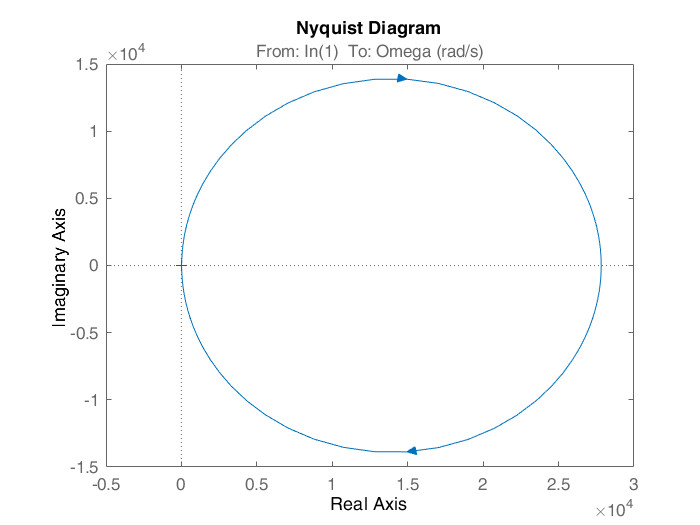

nyqDet=LoopT(1,1)*LoopT(2,2)-LoopT(1,2)*LoopT(2,1);
nyquist(nyqDet)

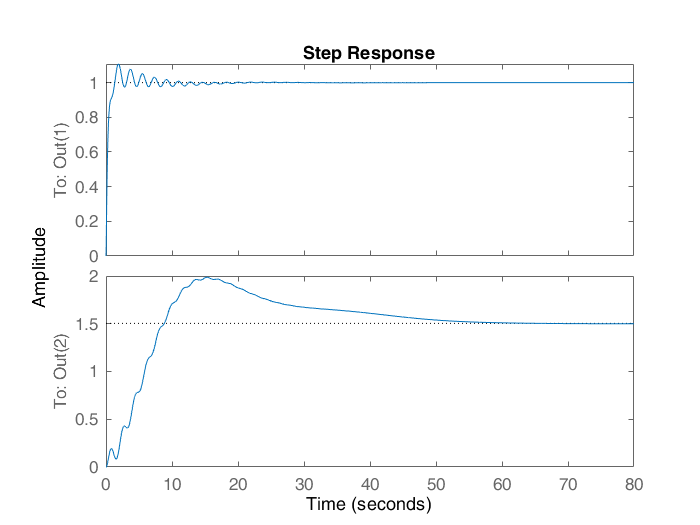

%sysL=feedback(P,K2)
Sens=(1/Wp)*CL2(1:2,1:2);
Compl=eye(2)-Sens;
step(Compl(1:2,1))

stepinfo(Compl(1:2,1))

ans = 2×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


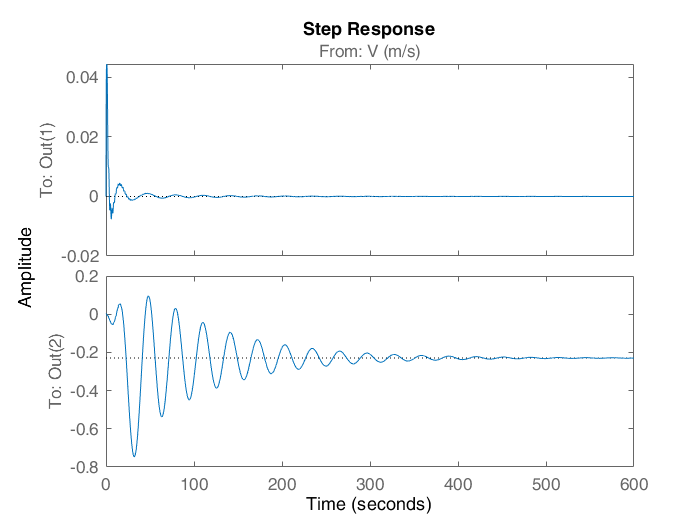


D_rej=Sens*FWT(1:2,3);
step(D_rej)

stepinfo(D_rej)

ans = 2×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime
